# DESS T2 Calculations from Dicom Files

% Load Dicom files from a directory and calculate the T2 Values

% Calculate T2 based on the ratio as described in:
% A simple analytic method for estimating T2 in the knee from DESS
% https://www.ncbi.nlm.nih.gov/pubmed/28017730

% Akshay Chaudhari 
% August 8th 2018

% PJL mods (01/03/22) for dealing with specific 7T dataset

## Specify known data information

clc; close all;

% Set the spoiler area and duration from acquisition
spl_area = 30; % (mT/m/s) choose the 30 or 50 dataset
spl_dur = 4.8e-3; % (s)   this was 4.8ms for both acquisitions

% Specify assumptions on T1 and diffusivity of tissue
T1 = 1.2; %(seconds) **you will need to find an estimate for the T1 of sciatic nerve @ 7T**
D = 1.25e-9; %(m^2/s) **you will need to find an estimate for the diffusivity of sciatic nerve @ 7T**

## Read data

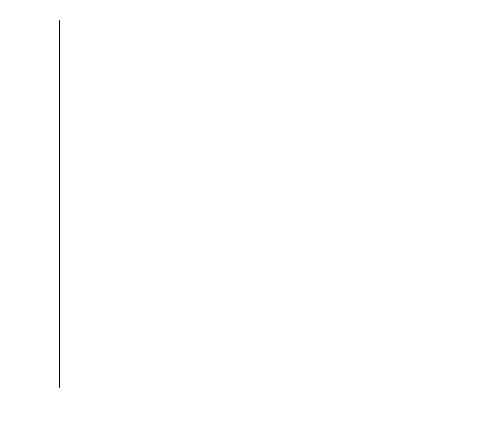

dicomDir = strcat('./spoil',num2str(spl_area),'/');
dicomFiles = dir([dicomDir,'*.IMA']);

% This is the area of the spoiler gradient in units (G/cm)*us
% For example, at 3G/cm a gradient being on for 1ms, GlArea = 3*1000 = 3000 
GlArea = spl_area*1e2; 

header = dicominfo(fullfile(dicomFiles(1).folder,dicomFiles(1).name));
r = header.Height;
c = header.Width;

% Preallocate array based on expected input size
img = zeros(r,c,length(dicomFiles));

for sl = 1:length(dicomFiles)
    img(:,:,sl) = dicomread(fullfile(dicomFiles(sl).folder,dicomFiles(sl).name));
end

% DESS Dicoms are stored a bit weird:
% 1.dcm = slice 1 echo 1, 2.dcm = slice 1 echo 2, and so on

dess(:,:,:,1) = img(:,:,1:end/2);
dess(:,:,:,2) = img(:,:,end/2+1:end);

clear img

## Calculate constants for T2 values

% All timing values should be in seconds
TR = header.RepetitionTime*1e-3;
TE = header.EchoTime*1e-3;
alpha = header.FlipAngle;

Gl = GlArea/(spl_dur*1e6)*100;
gamma = 4258*2*pi;	% Gamma, Rad/(G*s).
dkL = gamma*Gl*spl_dur;

% Simplifying the math here
% equation 6
k = (sind(alpha/2)).^2 .*(1 + exp(-TR/T1 - TR*dkL^2*D))./(1 - cosd(alpha)*exp(-TR/T1 - TR*dkL^2*D))

k = 0.5581

c1 = (TR-spl_dur/3)*dkL^2*D

c1 = 0.0017

## Do the T2 Fit

% Insert custom mask here - ones for now
mask = ones(r,c,length(dicomFiles)/2);

ratio = mask.*dess(:,:,:,2)./dess(:,:,:,1);
t2map = (-2000*(TR-TE)./(log(abs(ratio)./k)+c1));
display(t2map(1,1,1))

   NaN



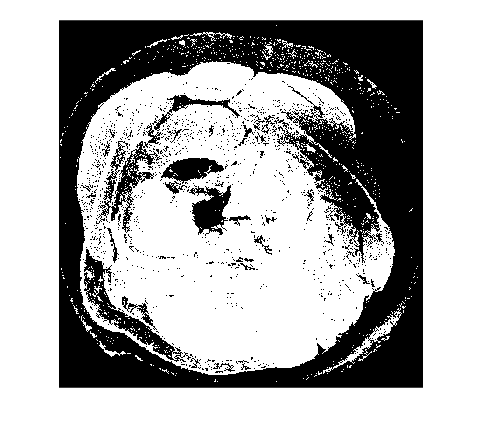

% Filter calculated T2 values that are below 0ms and over 100ms
t2map(t2map <=0) = NaN;
t2map(t2map > 100) = NaN;